## Testing script for *poissonSolver2D.m* by visualizing results

### Examples:

toggle the selection box in the cell below to switch between different examples.

#### Numerical setup:

clear all
global Delta DeltaT nG
global Ifi Ifim Ifip Ila Ilam Ilap
global Jfi Jfim Jfip Jla Jlam Jlap
global Ima Jma

Ima=50; Jma=50; Delta=0.1; DeltaT=0.1; nG=1;
Ifi = nG +1;   Ifim = Ifi -1; Ifip = Ifi +1;
Ila = Ima +nG; Ilam = Ila -1; Ilap = Ila +1;
Jfi = nG +1;   Jfim = Jfi -1; Jfip = Jfi +1;
Jla = Jma +nG; Jlam = Jla -1; Jlap = Jla +1;
ImaAll = Ima + 2*nG

ImaAll = 52

JmaAll = Jma + 2*nG

JmaAll = 52


rhouP = zeros(ImaAll, JmaAll, 2);
divPred = zeros(ImaAll, JmaAll);
p = zeros(ImaAll, JmaAll);
rhou = zeros(ImaAll, JmaAll, 2);
x = zeros(ImaAll, JmaAll, 2);
A = zeros(Ima*Jma, Ima*Jma);

BCs = [0, 1, 0, 0];

A = poissonKernel2D(A, BCs);

[X, Y] = ndgrid( linspace(-Delta, Delta*Ima, ImaAll), ...
    linspace(-Delta, Delta*Jma, JmaAll) );
x(:,:,1) = X;
x(:,:,2) = Y;

sel = 4

sel = 4


switch sel
    case 1
    %! Example 1
    rhouP(:,:,1) = 1.0;
    rhouP(:,:,2) = 0.0;
    case 2
    %! Example 2
    rhouP(:,:,1) = x(:,:,2) - (Jma/2 +1)*Delta;
    rhouP(:,:,2) = -x(:,:,1) + (Ima/2 +1)*Delta;
    case 3
    %! Example 3
    rhouP(:,:,1) = 1.0 - x(:,:,1) /(Ima*Delta);
    rhouP(:,:,2) = 0.;
    case 4
    %! Example 4
    is = Ima/2-5:Ima/2+5;
    js = Jma/2-5:Jma/2+5;
    rhouP(is,js,2) = 1;
    case 5
    %! Example 5
    is = Ima/2-5:Ima/2+5;
    js = Jma/2-5:Jma/2+5;
    rhouP(:,:,1) = 1.0 + x(:,:,2) - (Jma/2 +1)*Delta + 1.0 - x(:,:,1)/(Ima*Delta);
    rhouP(:,:,2) = -x(:,:,1) + (Ima/2 +1)*Delta;
    rhouP(is,js,2) = rhouP(is,js,2) + 1;
end

#### Predicted momentum:

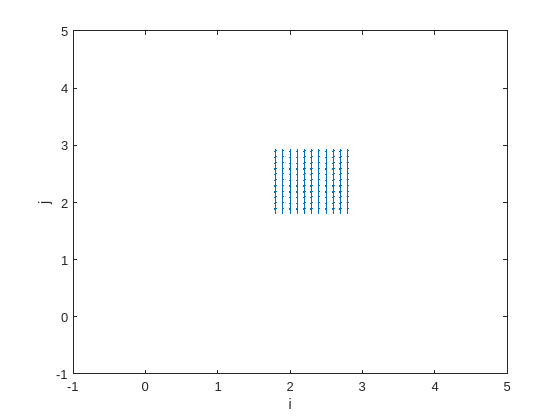

quiver(X, Y, rhouP(:,:,1), rhouP(:,:,2))
xlabel('i'); ylabel('j');

#### Divergence of momentum prediction:

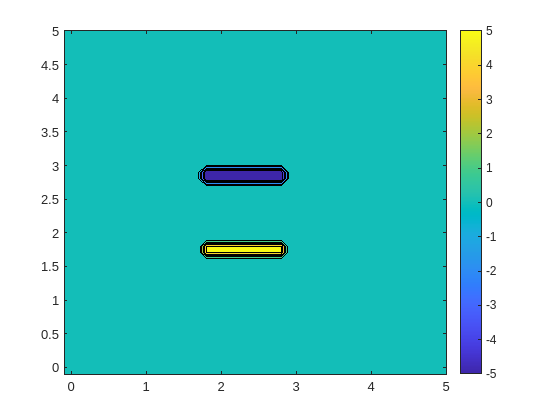

divPred = divMom2D(divPred, rhouP);
contourf(X,Y,divPred(:,:))
colorbar
grid off

#### Resulting pressure:

[p,I,e] = poissonSolver2D(p, divPred, A, BCs);
% [p,I,e] = poissonSolver2DBackSlash(p, divPred, A, BCs);
disp(I)

        5757



disp(e)

   9.9932e-07



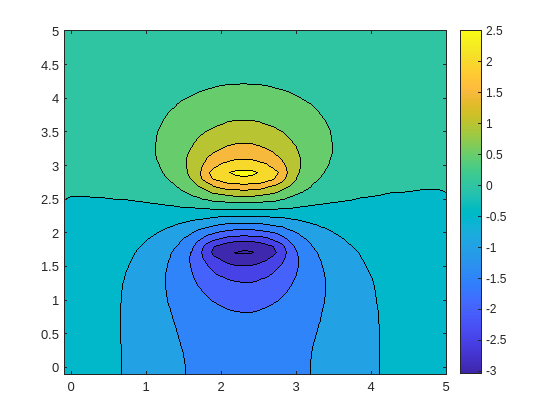

contourf(X,Y,p(:,:))
colorbar 
grid off

#### Momentum correction:

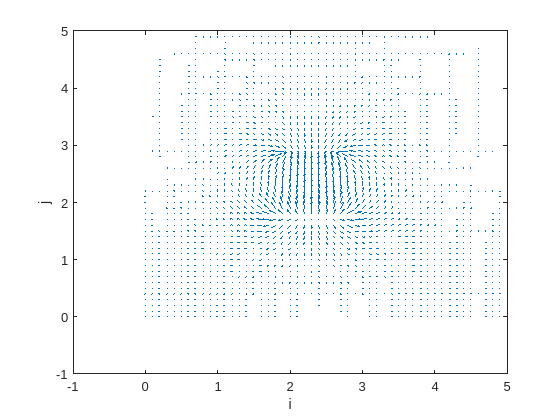

rhou = corrMom2D(rhou, rhouP, p);
corrRhou = rhouP - rhou;
quiver(X, Y, corrRhou(:,:,1), corrRhou(:,:,2))
%axis ji
%axis yx
xlabel("i")
ylabel("j")

#### Corrected momentum:

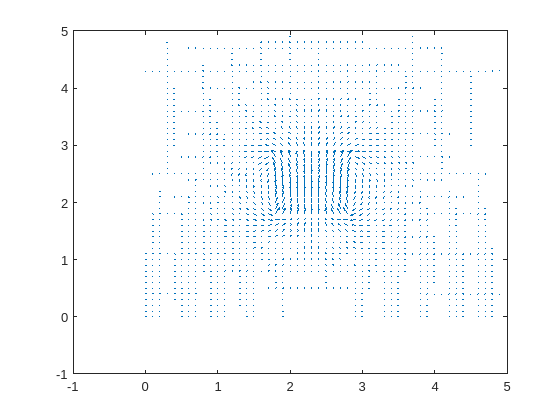

quiver(X, Y, rhou(:,:,1), rhou(:,:,2))

#### Correction for face velocity:

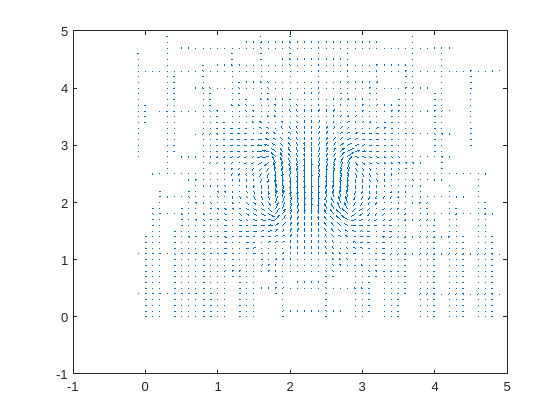

Ue = zeros(ImaAll, JmaAll);
Vn = zeros(ImaAll, JmaAll);
[Ue, Vn] = mom2vel(Ue,Vn,rhouP(:,:,1),rhouP(:,:,2));
[Ue, Vn] = corrVel2D(Ue,Vn,p);
quiver(X,Y,Ue,Vn)